# **Universe Record Nuke Throw**

*Authors: *Drew Pang and Omar Salih

A simulation and alternate ending to the movie [*The Avengers (2012)*](https://en.wikipedia.org/wiki/The_Avengers_(2012_film)#Plot).

## Question:

May 21st, 2012. Chaos is ravaging the city of New York, and the Chitauri's forces have enveloped the city. Thinking there is no end in sight, the World Security Council launches a nuke directly at Manhattan. Instead of Iron Man throwing it through the wormhole, however, Black Widow destroys the wormhole generator before the nuke can be thrown through. With the wormhole closed, the Chitauri's forces stop fighting due to losing communication with the mothership. Unfortunately, there is still a nuke aimed directly at New York City. Iron Man picks up the Hulk to intercept the nuke, but...

**Question: **What direction should Iron Man tell the Hulk to throw the nuke to get it as far away from the Earth as possible?

Iron Man's predicament is a design question because he is optimizing the angle at which the nuke is thrown from the Earth. The unintuitive nature of orbital physics makes this question interesting to not only us, but the Avengers, astrophysicists, daredevils, and astronauts. Of course, we will have more assumptions to further narrow the scope of our model and make calculations simpler for J.A.R.V.I.S. We will learn about the intricacies of orbital mechanics, and how complex the process of launching things into orbit truly is. 

## **Model:**

In order to answer our question, we need to abscrat our model to something more managable. We begin by placing the Earth in 2D space with the North Pole pointing directly out of the page. For simplicity, New York City is placed at the top of the 2D circle that is Earth. The launch angles from NYC are normal to the North Pole, and are shown in our schematic diagram:

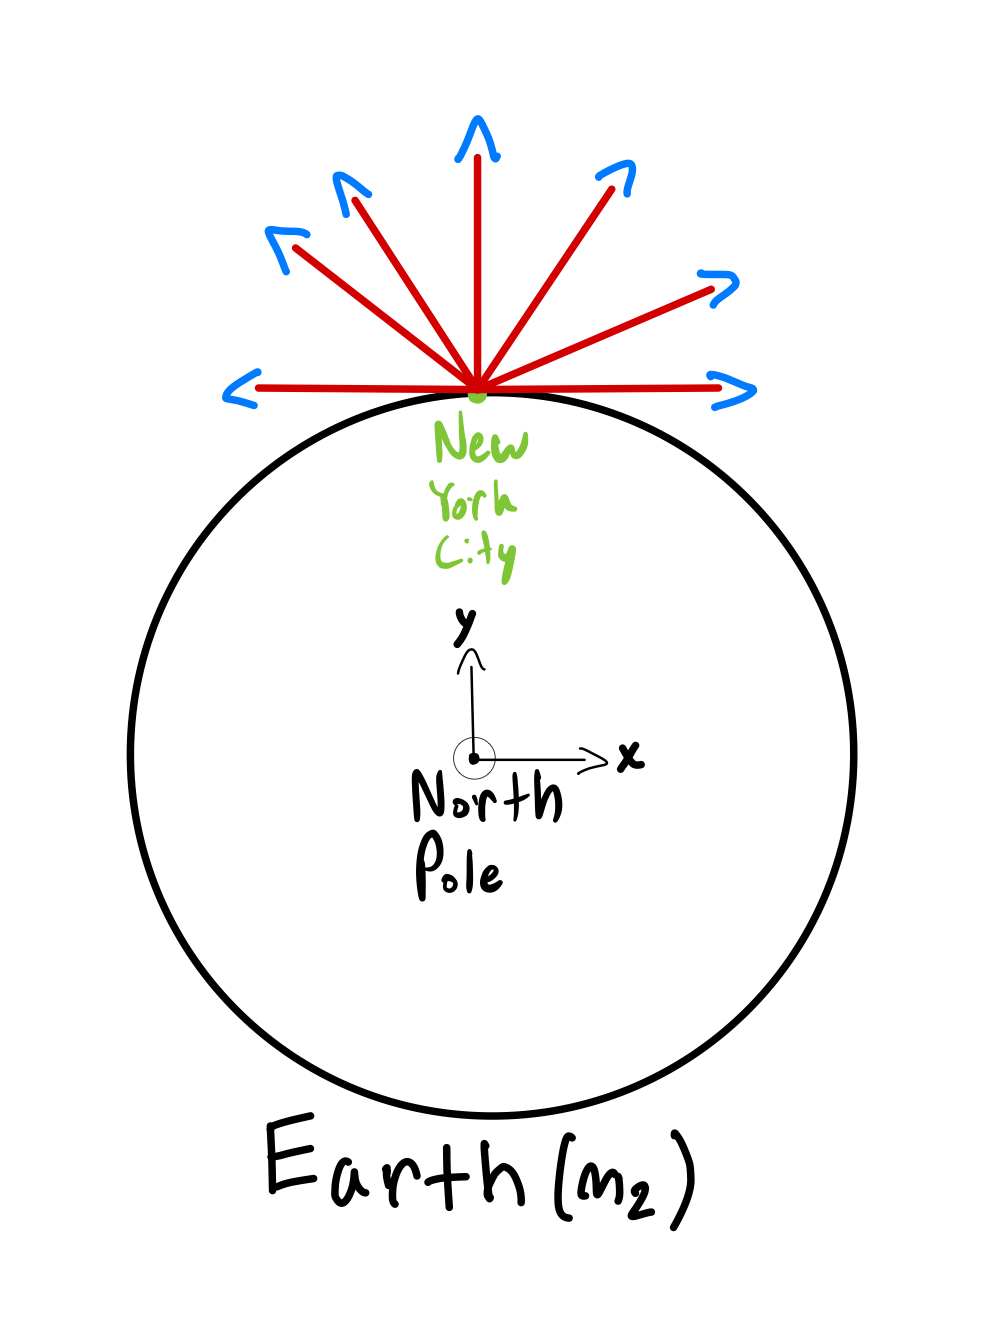

We also have additional assumptions to further define our system:

- Assumption 1

- Assumption 2

- Assumption 3

- Assumption 4

- Assumption 5

From our shcematic diagram, we can make a free body diagram:

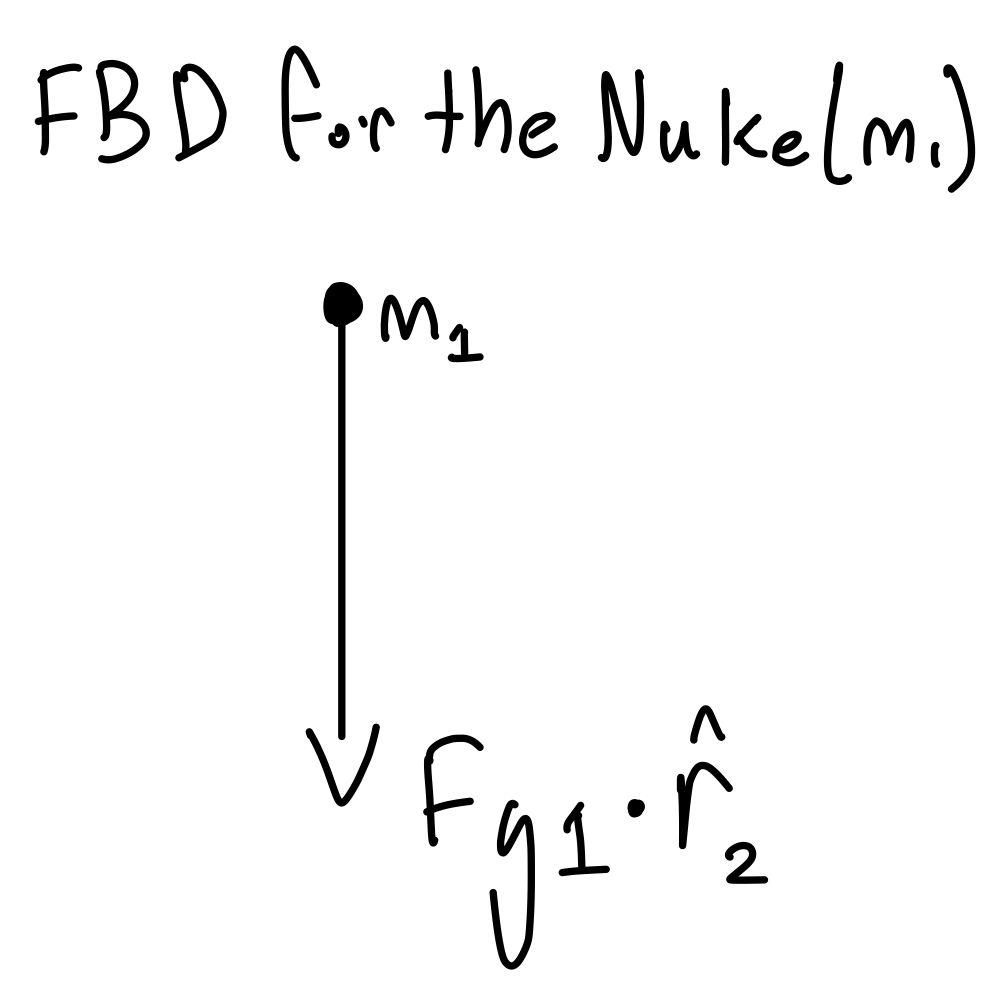

Where the only force is the Earth's gravity, and it changes based on the position vector of the nuke with respect to the Earth.

Now that we have a free body diagram, we can create our differential eqautions. As seen in worksheet 5, we will split our second order differential into two single order differentail eqautions with a change of variables:


$$\frac{d^2p}{dt^2} = \frac{Gm_2}{r_{2}^2}\hat{r_2}\\
\frac{dv}{dt} = \frac{Gm_2}{r_{2}^2}\hat{r_2}\\
\frac{dp}{dt} = \hat{v}$$


Where $r_2$ is the distance from the nuke to the center of the Earth, and $\hat{r_2}$ is a vector pointing in the direction of the nuke from the center of the Earth.

 For our first revision of the model, we will only consider the gravitational forces of Earth, but in the second revision we will add gravitational forces of the Sun and other planets in our solar system. Thus, we'll use $r_n$ and $\hat{r_n}$ for the nth body (Sun, Mercury, Mars, etc.)

Through internet reaserch, we were able to find values for all of the parameters of our system. 

**Parameters:**

**Model Veirfication:**

**Model Validation:**

**Prompts:**

- How are you going to answer your question? 

- What assumptions are you making? Are these good or bad assumptions?

- How did you develop and refine your model?

- What additional representations of your model help to communicate it to your reader (e.g., equations, stock and flow diagrams)? 

- How did you set the parameters of your model?

- How did you verify your model?

- Optional: If you had more time, what plan would you use to validate your model?

Assumptions:

- The Earth and Moon are stationary

- The Earth has no atmosphere, and thus there is not air resistance acting on the human

- The Earth and Moon are perfect spheres

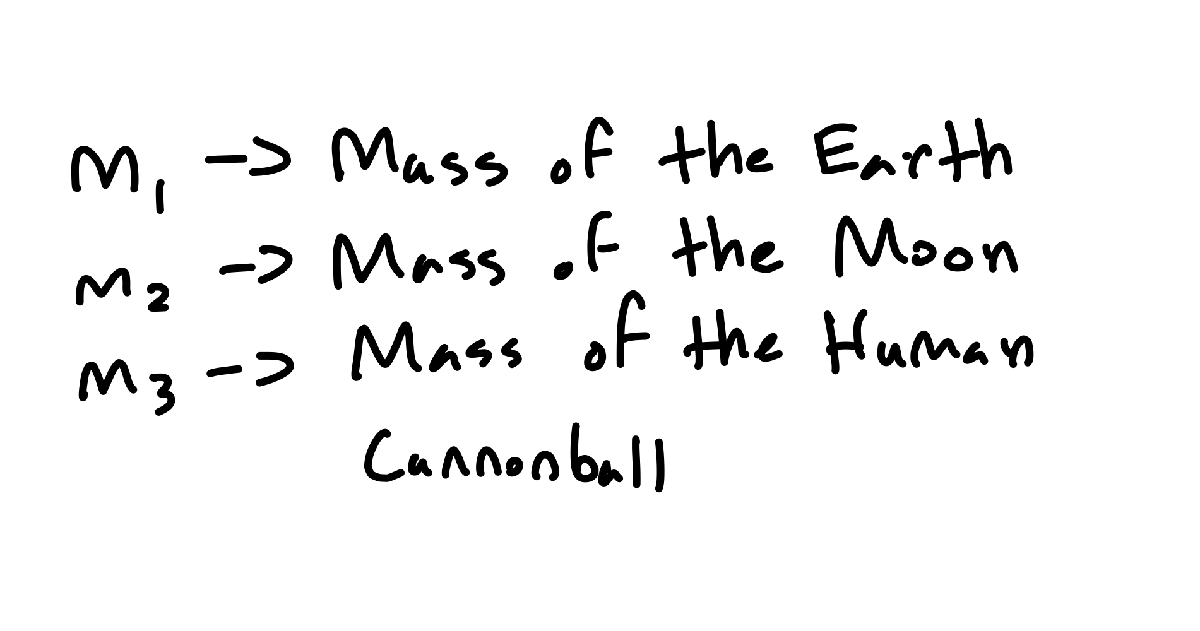


$$\frac{d^2p}{dt^2} = \frac{Gm_1}{r_{1}^2}\hat{r_1}+\frac{Gm_2}{r_{2}^2}\hat{r_2}\\
\frac{dv}{dt} = \frac{Gm_1}{r_{1}^2}\hat{r_1} + \frac{Gm_2}{r_{2}^2}\hat{r_2}\\
\frac{dp}{dt} = \hat{v}$$


earthVelocity = [11000,0]; % (m/s)

[T, M] = body_2D_ode45(earthVelocity);

clf;
hold on
plot(M(:,1), M(:,2));

% Plot Earth
points = linspace(0, 2*pi, 500);
r = 6.371e6;
x = r*cos(points);
y = r*sin(points);
plot(x,y)


% Plot Moon
points = linspace(0, 2*pi, 500);
r = 1.738e6;
x = r*cos(points) + 3.844e8;
y = r*sin(points);
plot(x,y)

xlabel('X Distance from Center of Earth');
ylabel('Y Distance from Center of Earth');
title('Body Orbit of Earth and Moon')

axis equal

## **Results:**

**Prompts:**

- What results did your model generate?

- Are there any key points of information in your results that  are most important or that will be most useful in your interpretation?  (Label key elements of your results figures.) 

## **Interpretation:** 

**Prompts:**

- How do the results answer the question?

- Do you think the answer is a good one? 

- What are the limitations of your model? 

- If you were going to continue developing your model, what next steps might you take? 

## Resources